# DC Test

clear 
clc


## Calibration

Vs_Plus = [14, 2, -4] * LSB_SUB

Vs_Plus =     0.7875    0.1125   -0.2250


Vs_Plus ./ LSB_SUB

ans =     14     2    -4


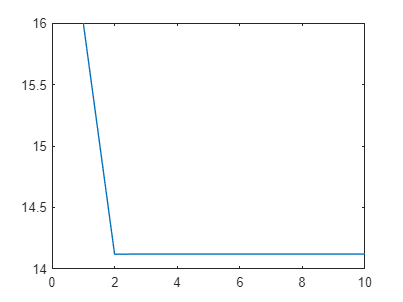

Gest_Plus =    16.0000   14.1204   14.1216   14.1216   14.1216   14.1216   14.1216   14.1216   14.1216   14.1216


Gest_Plus = Newton_Calib(Vs_Plus, 10)

GainA = Gest_Plus(4)

GainA = 14.1216

Vin = 0.6;
Vrefp = 1.8;
N_sub = 5;
LSB_SUB = Vrefp / 2^N_sub;

dout_orig = [11, -5, +5, -7];

vout_orig = dout_orig .* LSB_SUB;

Calib_Gain(vout_orig, GainA) * 1000

ans = 600.1042